# d=matlab.desktop.editor.findOpenDocument('/Users/matt/Documents/Codex/2026-10-14/referenced-chatgpt-conversation-this-is-an/outputs/three_link_robotics_live.mlx'); d.closeNoPrompt;

# validate_matlab_delivery; open('/Users/matt/Documents/Codex/2026-10-14/referenced-chatgpt-conversation-this-is-an/outputs/three_link_robotics_live.mlx');

# 平面竖直三连杆：从旋量到动力学与控制

MATLAB 实时脚本 · 中文教学版 · 31 节循序渐进的理论与实验

本文件由同名 Jupyter 教程转换，机器人学算法全部改写为 MATLAB。保留原来的模型、公式、验证与练习，使用 MATLAB 基础矩阵运算和绘图，不需要 Robotics System Toolbox、Symbolic Math Toolbox 或第三方库。

## 如何使用

打开 three_link_robotics_live.mlx，在实时编辑器中按顺序阅读。可运行全部内容，也可点击「运行节」独立执行某一节。每节自行调用 robot_model 建立参数；其余局部函数均在本文件末尾，不需要其他 .m 文件。

各节代码重新初始化 P，因此上一节修改的参数不会自动延续。要修改本节模型，可在 P=robot_model() 后更改 P.l、P.m、P.lc、P.Izz 或 P.g0。若长度/质量变化，质心和惯量需要同步重算。

MATLAB 统一使用列向量：q、dq、ddq、p 为 3×1；Slist、Blist、Js、Jb 的每一列对应一个关节。质心雅可比 Jv(:,:,i) 对应第 i 根杆，质量矩阵导数 dH(:,:,k) 对应对 q_k 求导。.*、.^ 是逐元素运算，* 是矩阵乘法，.' 是实数模型所用的转置，反斜杠用于求解线性方程。

## 分四次学习

• 第一次：00–09，建模、旋量原始定义、伴随与 POE。

• 第二次：10–15，空间/刚体雅可比、真实末端速度、奇异性与逆运动学。

• 第三次：16–23，质心雅可比、能量、质量矩阵、重力与完整动力学。

• 第四次：24–30，积分、能量检查、PD、重力补偿、计算力矩与力矩限幅。

## 版本与验证状态

建议使用 MATLAB R2021a 或更新版本。本文件已在本机 MATLAB R2026a Update 4 中完整执行：31 节实验、固定参考值与 20 个随机状态的集中自检全部通过，共生成 13 张图。还进行了 OPC/XML 文件结构检查与 MATLAB 代码分析。

本文件不继承 Python 的输出作为 MATLAB 运行结果。运行各节会生成对应数值、PASS 检查与图表。第 30 节给出集中数值自检，若任何断言不通过，MATLAB 会在相应位置报错。随机数生成器与绘图样式存在语言差异，因此无需要求随机构型、图形颜色与 Python 版逐像素一致。

随附的 three_link_robotics_source.m 是同一份 MATLAB 代码的普通脚本版本，可直接运行，也便于查看与修改源代码。两份文件均包含所需局部函数，不需要彼此配合。

## 00｜确认 MATLAB 环境与绘图

本教程只使用 MATLAB 自带的矩阵运算、线性方程求解、三角函数和基本绘图。单位统一为 m、kg、s、rad、N·m；输入角度若以度给出，用乘 pi/180 转成弧度。

下方应显示 MATLAB 版本和一张正弦曲线。图内使用英文，中文解释放在正文中。

P=robot_model(); format short g;
disp(['MATLAB version: ' version]);

MATLAB version: 26.1.0.3312084 (R2026a) Update 4


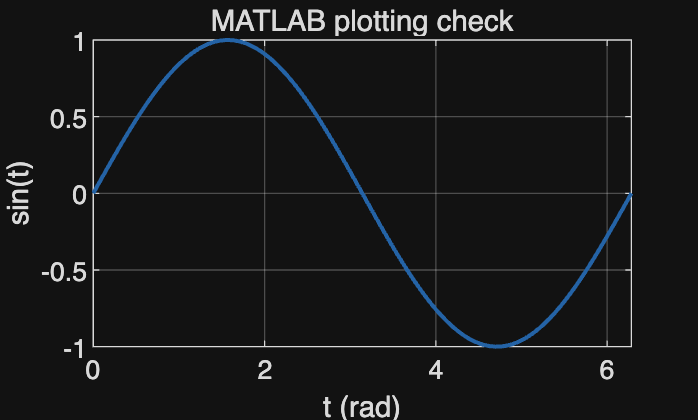

t=linspace(0,2*pi,100);
figure; plot(t,sin(t),'Color',P.colors(1,:),'LineWidth',1.5); grid on;
xlabel('t (rad)'); ylabel('sin(t)'); title('MATLAB plotting check');

disp('本教程只使用 MATLAB 基础函数。');

本教程只使用 MATLAB 基础函数。


## 01｜建模：关节角与连杆绝对朝向

空间系 $\{s\}$ 固定在基座：$x$ 向右、$y$ 向上、$z$ 朝向观察者。三根连杆在竖直 $xy$ 平面内运动，三个转轴均沿 $+z$，正角逆时针。$q_i$ 是相邻连杆间的**相对角**，不是第 $i$ 根杆的绝对朝向。


$$\alpha_i=\sum_{k=1}^i q_k,\qquad p_i=p_{i-1}+l_i[\cos\alpha_i,\ \sin\alpha_i,\ 0]^T.$$


$p_0=0$ 为基座；本节下标 $p_i$ 表示第 $i$ 根杆的远端，后文 POE 中的 `p0` 专指**所选刚体系零位原点**，留意语境。默认末端刚体系原点位于第三根杆末端，零位朝向与空间系一致。

**检查**：$q=0$ 时末端为 $(0.9,0,0)$。**练习**：只修改第二关节角，观察第三根杆为何也移动。

**对应函数**：robot_model、joint_points、fk_geom、draw_arm（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; pts=joint_points(P,q);
disp('relative q (deg):'); disp(q.'*180/pi);

relative q (deg):
           30          -45           60



disp('absolute alpha (deg):'); disp(cumsum(q).'*180/pi);

absolute alpha (deg):
           30          -15           45



disp('tip position (m):'); disp(pts(:,end).');

tip position (m):
      0.77761      0.26378            0



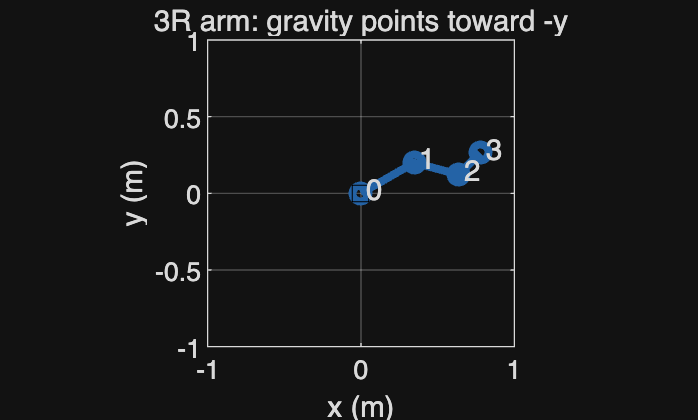

pts0=joint_points(P,zeros(3,1)); assert(norm(pts0(:,end)-[0.9;0;0])<1e-12);
figure; draw_arm(P,q);
for i=1:4, text(pts(1,i)+0.035,pts(2,i)+0.035,num2str(i-1)); end
title('3R arm: gravity points toward -y');

## 02｜齐次变换、反对称矩阵与伴随

齐次变换把旋转矩阵与原点位置组合起来：


$$T_{sb} =
\begin{bmatrix}
R & p \\
0_{1\times 3} & 1
\end{bmatrix}.$$


其中 $R\in\mathbb{R}^{3\times 3}$，$p=p_{sb}\in\mathbb{R}^{3}$ 是刚体系原点在空间系中的位置。$T_{sb}$ 把刚体系坐标转换到空间系：


$${}^s p_P = R\,{}^b p_P + p.$$


反对称矩阵用方括号表示，其作用等价于叉乘：


$$\left[\omega\right]x = \omega\times x.$$


本教程统一采用**角速度在前**的六维旋量：


$$V = \begin{bmatrix}\omega \\ v\end{bmatrix},
\qquad
\left[V\right] =
\begin{bmatrix}
\left[\omega\right] & v \\
0_{1\times 3} & 0
\end{bmatrix}.$$


这里 $V$ 是 $6\times 1$ 向量，$\left[V\right]$ 是 $4\times 4$ 矩阵；$\left[\omega\right]$ 是 $3\times 3$ 反对称矩阵。代码中的 `hat6(V)`、`skew3(w)` 分别实现这两种矩阵表示。

逆变换与伴随矩阵分别为：


$$T_{sb}^{-1} =
\begin{bmatrix}
R^T & -R^T p \\
0_{1\times 3} & 1
\end{bmatrix}.$$



$$\operatorname{Ad}_{T_{sb}} =
\begin{bmatrix}
R & 0_{3\times 3} \\
\left[p\right]R & R
\end{bmatrix}.$$


伴随矩阵的四个分块均为 $3\times 3$，整体为 $6\times 6$；左下分块的乘法顺序是 $\left[p\right]R$。

**检查**：叉乘、变换逆和伴随的矩阵共轭形式。**练习**：故意交换 $\left[p\right]R$ 的乘法次序，观察哪项检查不通过。

**对应函数**：skew3、hat6、vee6、invT、adjointT（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); w=[0.2;-0.4;0.7]; x=[1;2;3];
T=fk_geom(P,P.qdemo); V=[0;0;0.5;0.2;-0.1;0.3];
assert(norm(skew3(w)*x-cross(w,x))<1e-12);
assert(norm(T*invT(T)-eye(4),'fro')<1e-12);
assert(norm(hat6(adjointT(T)*V)-T*hat6(V)*invT(T),'fro')<1e-12);
disp('叉乘、逆变换、伴随共轭：PASS'); disp('T_sb ='); disp(T);

叉乘、逆变换、伴随共轭：PASS
T_sb =
      0.70711     -0.70711            0      0.77761
      0.70711      0.70711            0      0.26378
            0            0            1            0
            0            0            0            1



## 03｜从原始定义理解空间旋量与刚体旋量

对光滑刚体运动 $T(t)=[R(t),p(t)]$：


$$[V_s]=\dot T T^{-1},\quad \omega_s^\wedge=\dot RR^T,
\quad v_s=\dot p-\omega_s\times p;$$



$$[V_b]=T^{-1}\dot T,\quad \omega_b^\wedge=R^T\dot R,
\quad v_b=R^T\dot p.$$


因此 $v_b$ 是**所选刚体系原点的真实速度在刚体系中的表达**；$v_s$ 一般不等于原点速度 $\dot p$。对刚体上任意固定点 $P$，其真实速度满足


$${}^sv_P=\omega_s\times{}^sp_P+v_s,\qquad
{}^bv_P=\omega_b\times{}^bp_P+v_b.$$


注意：刚体固定点的 ${}^bp_P$ 是常量，故 $\frac{d}{dt}({}^bp_P)=0$；这**不表示真实速度** ${}^bv_P$ 为零。旋转坐标系下“坐标导数”和“真实速度的坐标表达”是两件事。

代码用独立几何正运动学与中心差分直接计算 $\dot T$，不借助雅可比。**练习**：把角速度和末端平移速度分别改成零，检查公式的简化。

**对应函数**：fk_geom、vee6、invT（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3]; h=1e-6;
T=fk_geom(P,q); dT=(fk_geom(P,q+h*dq)-fk_geom(P,q-h*dq))/(2*h);
Vs=vee6(dT*invT(T)); Vb=vee6(invT(T)*dT);
p=T(1:3,4); R=T(1:3,1:3); dp=dT(1:3,4);
disp('Vs=[ws;vs]:'); disp(Vs.'); disp('Vb=[wb;vb]:'); disp(Vb.');

Vs=[ws;vs]:
            0            0          0.5   -0.0032937     -0.12157            0

Vb=[wb;vb]:
            0            0          0.5     0.093373      0.28455            0



disp('真实原点速度 dp (m/s):'); disp(dp.');

真实原点速度 dp (m/s):
     -0.13518      0.26723            0



assert(norm(dp-cross(Vs(1:3),p)-Vs(4:6))<1e-8);
assert(norm(Vb(4:6)-R.'*dp)<1e-8);
assert(norm(Vs-adjointT(T)*Vb)<1e-8);
pb=[0.08;0.02;0]; vP_b=Vb(4:6)+cross(Vb(1:3),pb);
Tp=fk_geom(P,q+h*dq); Tm=fk_geom(P,q-h*dq);
vP_fd=(Tp(1:3,1:3)*pb+Tp(1:3,4)-Tm(1:3,1:3)*pb-Tm(1:3,4))/(2*h);
assert(norm(R*vP_b-vP_fd)<1e-8);
disp('固定刚体点：坐标导数为0，真实 vP_b 为'); disp(vP_b.');

固定刚体点：坐标导数为0，真实 vP_b 为
     0.083373      0.32455            0



## 04｜零位空间轴 $S_i$：从速度定义到轴几何

令机器人在零位，只让关节 $i$ 以 $1\,\mathrm{rad/s}$ 转动。$r_i^s$ 是**从空间原点指向该转轴上一点的位置向量**，$p_0$ 是零位末端原点。


$$\dot p_i^s=\omega_i^s\times(p_0-r_i^s),\qquad
v_i^s=\dot p_i^s-\omega_i^s\times p_0=-\omega_i^s\times r_i^s.$$



$$S_i=[\omega_i^s;v_i^s].$$


默认 $r_1^s=(0,0,0),r_2^s=(0.4,0,0),r_3^s=(0.7,0,0)$，故三列 $v_i^s$ 的 $y$ 分量为 $0,-0.4,-0.7$。`Slist` 是**零位常量轴**；运动中的瞬时轴稍后由空间雅可比给出。

**练习**：在同一条轴上把 $r_i$ 加上 $(0,0,2)$，为什么 $S_i$ 不变？

**对应函数**：home_axes（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); l=P.l; p0=[sum(l);0;0]; wi=[0;0;1];
ri=[0 l(1) l(1)+l(2);zeros(2,3)];
S_original=zeros(6,3); S_geometry=zeros(6,3); h=1e-6; E3=eye(3);
for i=1:3
    dpi=cross(wi,p0-ri(:,i)); vi=dpi-cross(wi,p0);
    S_original(:,i)=[wi;vi]; S_geometry(:,i)=[wi;-cross(wi,ri(:,i))];
    ei=E3(:,i); dTi=(fk_geom(P,h*ei)-fk_geom(P,-h*ei))/(2*h);
    assert(norm(vee6(dTi*invT(fk_geom(P,zeros(3,1))))-S_original(:,i))<1e-8);
end
Slist=S_geometry; assert(norm(Slist-S_original,'fro')<1e-12);
disp('Slist ='); disp(Slist);

Slist =
            0            0            0
            0            0            0
            1            1            1
            0            0            0
            0         -0.4         -0.7
            0            0            0



## 05｜零位刚体轴 $B_i$：允许 $R_0\ne I$


$$\omega_i^b=R_0^T\omega_i^s,\quad r_i^b=R_0^T(r_i^s-p_0),$$



$$v_i^b=R_0^T\dot p_i^s=-\omega_i^b\times r_i^b,\qquad B_i=[\omega_i^b;v_i^b].$$


这里 $r_i^b$ 是**从所选刚体系原点指向转轴点**的向量，方向不要取反。默认 $\phi_0=0$，三列 $v_i^b$ 的 $y$ 分量为 $0.9,0.5,0.2$。把 $\phi_0$ 改为 $30^\circ$ 只是重新选择末端坐标系方向，不改变实体杆的零位形状。

**练习**：把 `phi0` 改为 0 和 90°，比较 `Blist`；不要把它理解成机器人实际关节转了相同角度。

**对应函数**：home_axes、rotz3（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); l=P.l; phi0=30*pi/180; R0=rotz3(phi0);
p0=[sum(l);0;0]; ri_s=[0 l(1) l(1)+l(2);zeros(2,3)]; wi_s=[0;0;1];
Blist=zeros(6,3);
for i=1:3
    wi_b=R0.'*wi_s; ri_b=R0.'*(ri_s(:,i)-p0);
    dpi_s=cross(wi_s,p0-ri_s(:,i)); vi_b=R0.'*dpi_s;
    assert(norm(vi_b+cross(wi_b,ri_b))<1e-12);
    Blist(:,i)=[wi_b;vi_b];
end
disp('phi0=30 deg, Blist ='); disp(Blist);

phi0=30 deg, Blist =
            0            0            0
            0            0            0
            1            1            1
         0.45         0.25          0.1
      0.77942      0.43301      0.17321
            0            0            0



p0_new=ri_s(:,3); vb3_new=R0.'*cross(wi_s,p0_new-ri_s(:,3));
assert(norm(vb3_new)<1e-12); disp('原点在关节3轴上，vb3 ='); disp(vb3_new.');

原点在关节3轴上，vb3 =
     0     0     0



## 06｜伴随转换：同一运动，两种坐标表达

原始定义给出 $[V_s]=T[V_b]T^{-1}$，因此


$$V_s=\operatorname{Ad}_TV_b,\qquad B_i=\operatorname{Ad}_{M^{-1}}S_i.$$


这里 $M=T(0)$ 是零位末端变换。`Slist` 和 `Blist` 都是零位定义的常量；任意时刻的 $V_s,V_b$ 则要用当前 $T(q)$ 转换，不能一直用 $M$。

**检查**：伴随、共轭与直接轴几何在非零 `phi0` 下完全一致。

**对应函数**：adjointT、home_axes（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); [M,Slist,Blist]=home_axes(P,30*pi/180);
assert(norm(Blist-adjointT(invT(M))*Slist,'fro')<1e-12);
for i=1:3
    assert(norm(hat6(Blist(:,i))-invT(M)*hat6(Slist(:,i))*M,'fro')<1e-12);
end
disp('Slist ='); disp(Slist); disp('Blist ='); disp(Blist);

Slist =
            0            0            0
            0            0            0
            1            1            1
            0            0            0
            0         -0.4         -0.7
            0            0            0

Blist =
            0            0            0
            0            0            0
            1            1            1
         0.45         0.25          0.1
      0.77942      0.43301      0.17321
            0            0            0



disp('伴随与矩阵共轭：PASS');

伴随与矩阵共轭：PASS


## 07｜把单轴旋转写成矩阵指数

对于 $\|\omega\|=1$ 的转动轴，记 $W=[\omega]$：


$$e^{W\theta}=I+\sin\theta W+(1-\cos\theta)W^2,$$



$$e^{[S]\theta}=\begin{bmatrix}e^{W\theta}&G(\theta)v\\0&1\end{bmatrix},\qquad
G(\theta)=I\theta+(1-\cos\theta)W+(\theta-\sin\theta)W^2.$$


纯移动轴 $\omega=0$ 时，旋转为 $I$，平移为 $v\theta$。代码使用小角度级数和稳定的三角恒等式，减小数值抵消，不改变公式。本函数的转动轴必须单位化，关节角单独放在 `theta` 中。

**检查**：轴上的点保持不动；正角再负角恢复原位。**练习**：取 $\theta=10^{-10}$，观察结果是否仍有限。

**对应函数**：exp_twist（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); [~,Slist,~]=home_axes(P); S=Slist(:,2); theta=0.6;
T=exp_twist(S,theta); r_axis=[P.l(1);0;0;1];
assert(norm(T*r_axis-r_axis)<1e-12);
assert(norm(T*exp_twist(S,-theta)-eye(4),'fro')<1e-12);
assert(norm(T(1:3,1:3).'*T(1:3,1:3)-eye(3),'fro')<1e-12);
assert(abs(det(T(1:3,1:3))-1)<1e-12);
Ttiny=exp_twist(S,1e-10); assert(all(isfinite(Ttiny(:))));
disp('exp([S2] theta) ='); disp(T);

exp([S2] theta) =
      0.82534     -0.56464            0     0.069866
      0.56464      0.82534            0     -0.22586
            0            0            1            0
            0            0            0            1



## 08｜空间 POE 与刚体 POE 正运动学


$$T(q)=e^{[S_1]q_1}e^{[S_2]q_2}e^{[S_3]q_3}M
=M e^{[B_1]q_1}e^{[B_2]q_2}e^{[B_3]q_3}.$$


两种乘积的关节次序都是 1、2、3；区别是 $M$ 放在哪里，以及用哪套常量轴。矩阵乘法不能交换顺序。

我们再用第 01 节三角函数几何结果作为独立参考，随机抽样比较。**练习**：交换空间 POE 中第 1、2 个指数，检查误差为什么出现。

**对应函数**：fk_space、fk_body（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); rng(7); max_error=0;
for sample=1:30
    q=-1.5+3*rand(3,1);
    for phi0=[0 0.4]
        Ts=fk_space(P,q,phi0); Tb=fk_body(P,q,phi0); Tg=fk_geom(P,q,phi0);
        max_error=max([max_error,norm(Ts-Tb,'fro'),norm(Ts-Tg,'fro')]);
    end
end
assert(max_error<1e-10);
fprintf('30 configurations x 2 frame orientations: max error = %.3e\n',max_error);

30 configurations x 2 frame orientations: max error = 5.551e-16


disp('T(q_demo) ='); disp(fk_space(P,P.qdemo));

T(q_demo) =
      0.70711     -0.70711            0      0.77761
      0.70711      0.70711            0      0.26378
            0            0            1            0
            0            0            0            1



## 09｜更换刚体系原点：同时修正几何验证

把零位刚体系原点移到第三关节轴 $p_0'=(l_1+l_2,0,0)$，并设零位方向 $R_0'$。新变换 $T'$ 描述这个**新坐标系**，不能再把它的平移与原末端位置直接比较。

原末端在新刚体系中的固定坐标为


$$r_{tip}^{b'}=R_0'^T([l_1+l_2+l_3,0,0]^T-p_0'),\qquad
p_{tip}^s=R' r_{tip}^{b'}+p'.$$


第三关节单独旋转时，新原点静止，所以 $B_3'$ 的线速度为零；原末端仍然运动。这里附着坐标系选在第三根杆近端，仍随第三根杆转动。

**练习**：只令 $q_3$ 改变，分别打印新原点位置和重建的真实末端位置。

**对应函数**：home_axes、fk_space、fk_body（均在文末，可先读本节实验，再查看函数实现）。

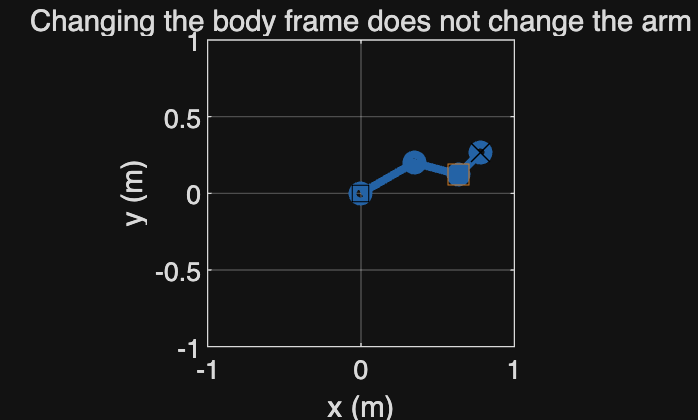

P=robot_model(); q=P.qdemo; phi0=30*pi/180;
p0_new=[P.l(1)+P.l(2);0;0]; [Mnew,~,Bnew]=home_axes(P,phi0,p0_new);
Tnew=fk_body(P,q,phi0,p0_new);
rtip_b=Mnew(1:3,1:3).' * ([sum(P.l);0;0]-p0_new);
ptip=Tnew(1:3,1:3)*rtip_b+Tnew(1:3,4); pts=joint_points(P,q);
assert(norm(Bnew(4:6,3))<1e-12);
assert(norm(Tnew-fk_space(P,q,phi0,p0_new),'fro')<1e-12);
assert(norm(ptip-pts(:,end))<1e-12);
figure; draw_arm(P,q); hold on;
plot(Tnew(1,4),Tnew(2,4),'s','MarkerSize',10,'Color',P.colors(2,:));
plot(ptip(1),ptip(2),'kx','MarkerSize',10); hold off;
title('Changing the body frame does not change the arm');

disp('B3_new ='); disp(Bnew(:,3).');

B3_new =
            0            0            1  -1.6653e-17   2.7357e-17            0



## 10｜空间雅可比：逐列搬运零位轴


$$V_s=J_s(q)\dot q,\qquad
J_{s,i}=\operatorname{Ad}_{e^{[S_1]q_1}\cdots e^{[S_{i-1}]q_{i-1}}}S_i.$$


第一列没有前序关节，因此 $J_{s,1}=S_1$。第 $i$ 列只依赖前面的关节，表达“当前构型下只给关节 $i$ 单位角速度时，整个末端刚体的空间旋量”。

代码维护 `Tprev`，先计算当前列再乘当前关节指数。用 $\dot T T^{-1}$ 的数值结果验证，不靠另一个雅可比函数自证。

**对应函数**：jac_space（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3]; h=1e-6;
Js=jac_space(P,q); T=fk_geom(P,q);
dT=(fk_geom(P,q+h*dq)-fk_geom(P,q-h*dq))/(2*h);
Vs_fd=vee6(dT*invT(T));
assert(norm(Js*dq-Vs_fd)<1e-8);
disp('Js ='); disp(Js); disp('Js*dq ='); disp((Js*dq).');

Js =
            0            0            0
            0            0            0
            1            1            1
            0          0.2      0.12235
            0     -0.34641     -0.63619
            0            0            0

Js*dq =
            0            0          0.5   -0.0032937     -0.12157            0



fprintf('definition residual = %.3e\n',norm(Js*dq-Vs_fd));

definition residual = 5.936e-11


## 11｜刚体雅可比：从后往前构造


$$V_b=J_b(q)\dot q,\qquad
J_{b,i}=\operatorname{Ad}_{e^{-[B_3]q_3}\cdots e^{-[B_{i+1}]q_{i+1}}}B_i.$$


最后一列 $J_{b,3}=B_3$。逆序指数的顺序不可颠倒。例如 $J_{b,1}=\operatorname{Ad}_{e^{-[B_3]q_3}e^{-[B_2]q_2}}B_1$。


$$J_b=\operatorname{Ad}_{T(q)^{-1}}J_s.$$


**检查**：直接逆序构造、当前位姿伴随、$T^{-1}\dot T$ 三条路径一致，且允许非零末端坐标系朝向。

**对应函数**：jac_body（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3]; h=1e-6; phi0=0.4;
T=fk_geom(P,q,phi0); Jb=jac_body(P,q,phi0);
dT=(fk_geom(P,q+h*dq,phi0)-fk_geom(P,q-h*dq,phi0))/(2*h);
assert(norm(Jb-adjointT(invT(T))*jac_space(P,q),'fro')<1e-10);
assert(norm(Jb*dq-vee6(invT(T)*dT))<1e-8);
disp('Jb ='); disp(Jb);

Jb =
            0            0            0
            0            0            0
            1            1            1
      0.62141       0.3756     0.077884
      0.53675       0.2212      0.18421
            0            0            0



fprintf('body velocity residual = %.3e\n',norm(Jb*dq-vee6(invT(T)*dT)));

body velocity residual = 8.683e-11


## 12｜末端真实速度：$J_s$ 下半部分不能直接拿来用

设 $p$ 是当前末端原点的空间位置：


$$\dot p=\omega_s\times p+v_s
=\underbrace{\left(-[p]J_s^\omega+J_s^v\right)}_{J_p}\dot q
=R\,J_b^v\dot q.$$


默认刚体系原点就是末端，所以 $J_b^v\dot q$ 是末端真实速度在刚体系中的表达。$J_p$ 是空间系下的点速度雅可比，与 $J_s$ 的线速度块含义不同。

若换过刚体系原点，对原末端要加上 $\omega_b\times r_{tip}^b$。本单元重新使用默认末端原点。

**练习**：只给第一关节角速度，此时 $J_s^v$ 第一列是零，但末端显然沿圆弧运动。用打印结果解释原因。

**对应函数**：jac_point（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3]; h=1e-6;
T=fk_geom(P,q); Jb=jac_body(P,q); Js=jac_space(P,q);
v1=jac_point(P,q)*dq; v2=T(1:3,1:3)*(Jb(4:6,:)*dq);
pp=joint_points(P,q+h*dq); pm=joint_points(P,q-h*dq); v3=(pp(:,end)-pm(:,end))/(2*h);
assert(norm(v1-v2)<1e-10 && norm(v1-v3)<1e-8);
disp('真实末端速度 (m/s):'); disp(v1.');

真实末端速度 (m/s):
     -0.13518      0.26723            0



disp('空间旋量线速度分量:'); disp((Js(4:6,:)*dq).');

空间旋量线速度分量:
   -0.0032937     -0.12157            0



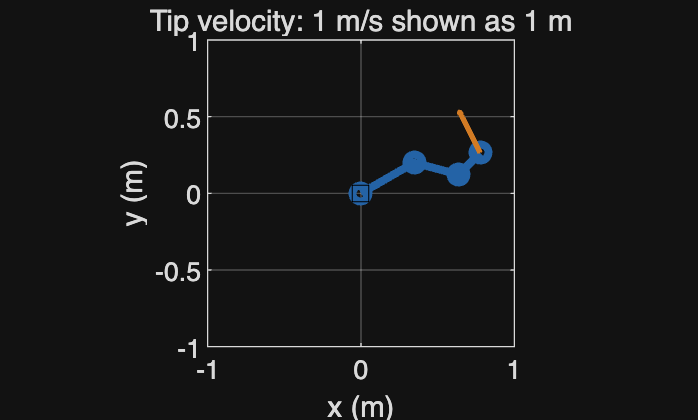

figure; draw_arm(P,q); hold on;
quiver(T(1,4),T(2,4),v1(1),v1(2),0,'Color',P.colors(2,:),'LineWidth',2); hold off;
title('Tip velocity: 1 m/s shown as 1 m');

## 13｜奇异性：根据任务选择雅可比

对平面位置任务 $(x,y)$ 使用 $2\times3$ 的 $J_{xy}$；对平面位姿 $(x,y,\phi)$ 使用 $3\times3$ 的 $J_{xy\phi}$：


$$J_{xy\phi}=\begin{bmatrix}J_p^{x}\\J_p^{y}\\1\;1\;1\end{bmatrix}.$$


所有平面机器人的 $6\times3$ 空间雅可比都有三条受约束的空间方向，判断奇异性时不要要求它具备六维满秩。伸直时位置雅可比秩降为 1，瞬时不能沿杆方向移动。

位置与角度单位不同，分析位姿条件数时应引入长度尺度；本节只对单位一致的 $J_{xy}$ 作奇异值分解。**练习**：比较 $q_2=0$、$q_3\ne0$ 时，位置任务和完整位姿任务的秩是否相同。

**对应函数**：jac_point（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); qs=[zeros(3,1),P.qdemo]; names={'straight','bent'};
for k=1:2
    Jp=jac_point(P,qs(:,k)); Jxy=Jp(1:2,:); Jpose=[Jxy;ones(1,3)];
    fprintf('%s: position rank %d, pose rank %d\n',names{k},rank(Jxy),rank(Jpose));
    disp('position singular values:'); disp(svd(Jxy).');
end

straight: position rank 1, pose rank 2


position singular values:
       1.0488            0



bent: position rank 2, pose rank 3


position singular values:
      0.94376      0.11653



Jp0=jac_point(P,zeros(3,1)); Jpd=jac_point(P,P.qdemo);
assert(rank(Jp0(1:2,:))==1 && rank(Jpd(1:2,:))==2);


## 14｜数值逆运动学：阻尼最小二乘

对位置或位姿误差 $e$ 进行局部线性化：$e\approx J\Delta q$。使用


$$\Delta q=\widetilde J^T(\widetilde J\widetilde J^T+\lambda^2I)^{-1}\widetilde e,
\quad \widetilde J=WJ,\quad \widetilde e=We.$$


仅位置任务 $W=I_2$；位姿任务 $W=\operatorname{diag}(1,1,L_{ref})$，把 rad 姿态误差换成 m 尺度。姿态差用 `wrap` 映射到 $[-\pi,\pi)$。代码通过 MATLAB 的反斜杠运算符 解线性方程，不显式求逆；限制单步关节变化，再做误差下降回溯。

逆解不保证全局收敛，也不唯一。示例没有关节限位、自碰撞与障碍物；阻尼能改善近奇异数值问题，却不能让不可达目标变可达。位置目标即使在总长度圆内，也仍应检查最终残差。

**练习**：换初值，比较不同位置逆解；把目标改为 $(1.2,0)$，应返回失败而非假装成功。

**对应函数**：ik_dls、jac_planar、ik_error（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q_seed=[15;-30;20]*pi/180; q_known=[40;-65;50]*pi/180;
pts=joint_points(P,q_known); target_pose=[pts(1:2,end);sum(q_known)];
[q_pos,ok_pos,hp]=ik_dls(P,target_pose(1:2),q_seed,false);
[q_pose,ok_pose,hf]=ik_dls(P,target_pose,q_seed,true);
assert(ok_pos && ok_pose);
pts_sol=joint_points(P,q_pose); assert(norm(pts_sol(1:2,end)-target_pose(1:2))<1e-7);
assert(abs(wrap_angle(sum(q_pose)-target_pose(3)))<1e-7);
[~,ok_bad,hb]=ik_dls(P,[1.2;0],q_seed,false); assert(~ok_bad);
disp('position IK q(deg):'); disp(q_pos.'*180/pi);

position IK q(deg):
       46.015       -65.16       26.449



disp('pose IK q(deg):'); disp(q_pose.'*180/pi);

pose IK q(deg):
           40          -65           50



fprintf('unreachable target: success=%d, residual=%.6f m\n',ok_bad,hb(end));

unreachable target: success=0, residual=0.300087 m


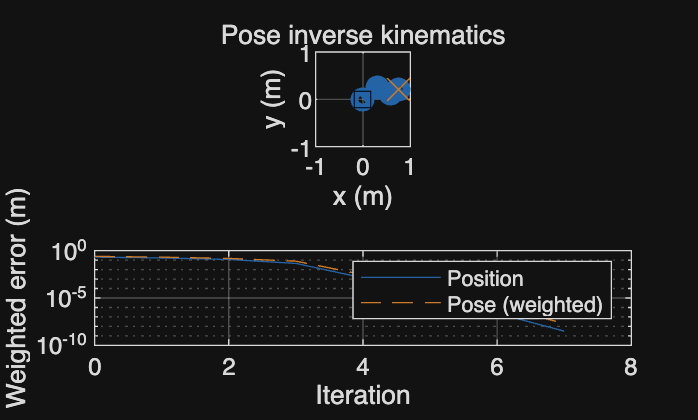

figure; subplot(2,1,1); draw_arm(P,q_pose); hold on;
plot(target_pose(1),target_pose(2),'x','MarkerSize',12,'Color',P.colors(2,:)); hold off;
title('Pose inverse kinematics');
subplot(2,1,2); semilogy(0:numel(hp)-1,hp,'-','Color',P.colors(1,:)); hold on;
semilogy(0:numel(hf)-1,hf,'--','Color',P.colors(2,:)); hold off; grid on;
xlabel('Iteration'); ylabel('Weighted error (m)'); legend({'Position','Pose (weighted)'});

## 15｜末端受力如何变成关节力矩：虚功检查

从真实点速度 $v=J_p\dot q$ 与功率守恒得到


$$\tau_{ext}=J_p^Tf_s,\qquad \tau_{ext}^T\dot q=f_s^T\dot p.$$


$f_s$ 是**环境施加于机器人末端**的力，单位 N，本节只考虑末端的力、没有末端力偶。完整六维扳手的变换需要同时处理力矩参考点，不能直接把 $J_s^v$ 当作 $J_p$ 来用。

**练习**：令末端受到竖直向下的力，观察哪些关节需要更大的静态支撑力矩。

**对应函数**：jac_point（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.3;-0.1;0.2]; f_s=[2;-5;0];
Jp=jac_point(P,q); tau_ext=Jp.'*f_s;
power_joint=tau_ext.'*dq; power_tip=f_s.'*(Jp*dq);
assert(abs(power_joint-power_tip)<1e-12);
disp('environment joint torque (Nm):'); disp(tau_ext.');

environment joint torque (Nm):
      -4.4156      -2.2835     -0.98995



fprintf('power at joints / tip (W): %.6f / %.6f\n',power_joint,power_tip);

power at joints / tip (W): -1.294315 / -1.294315


## 16｜质心与质心雅可比：动力学从这里开始

假设各杆均匀、刚性，质量为 $m_i$，质心距近端 $l_{ci}=l_i/2$，关于质心垂直平面的惯量 $I_{zi}=m_il_i^2/12$。忽略电机转子、减速器、摩擦、弹性与末端载荷。


$$p_{ci}=p_{i-1}+l_{ci}[\cos\alpha_i,\sin\alpha_i,0]^T.$$


对能影响第 $i$ 根杆的关节 $j\le i$：


$$J_{vi,j}=\hat z\times(p_{ci}-p_{j-1}),\qquad J_{\omega i,j}=\hat z.$$


对 $j>i$ 两列均为零。于是 $v_{ci}=J_{vi}\dot q,\ \omega_i=J_{\omega i}\dot q$。

`Jv(:,j,i)` 表示第 $i$ 根杆关于关节 $j$ 的那一列；MATLAB 与公式均从 1 编号。**检查**：各质心三条速度列都用位置差分验证。**练习**：把第三根杆质心移到近端 80% 处，同时明确惯量需要怎样重新设定。

**对应函数**：com_data（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; h=1e-6; E3=eye(3);
[pc,Jv,Jw]=com_data(P,q);
for j=1:3
    e=h*E3(:,j); [pcp,~,~]=com_data(P,q+e); [pcm,~,~]=com_data(P,q-e);
    dpc=(pcp-pcm)/(2*h);
    for i=1:3, assert(norm(Jv(:,j,i)-dpc(:,i))<1e-8); end
end
assert(norm(Jv(:,2:3,1),'fro')<1e-12);
disp('COM positions, columns are links (m):'); disp(pc);

COM positions, columns are links (m):
      0.17321       0.4913       0.7069
          0.1      0.16118      0.19306
            0            0            0



disp('link 2 Jv ='); disp(Jv(:,:,2));

link 2 Jv =
     -0.16118     0.038823            0
       0.4913      0.14489            0
            0            0            0



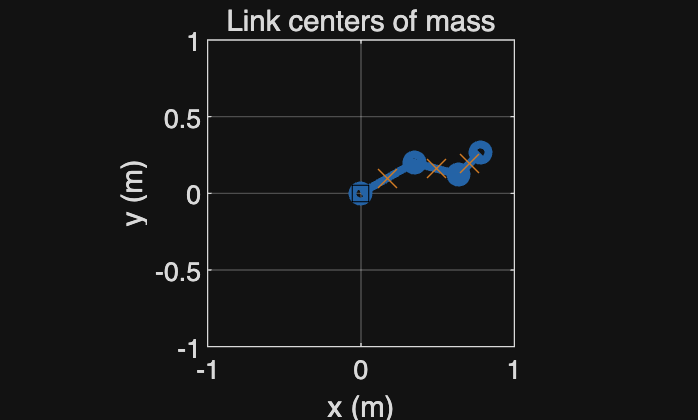

figure; draw_arm(P,q); hold on; plot(pc(1,:),pc(2,:),'x','MarkerSize',10,'Color',P.colors(2,:)); hold off;
title('Link centers of mass');

## 17｜动能、势能与拉格朗日函数


$$K=\frac12\sum_i\left(m_i v_{ci}^Tv_{ci}+I_{zi}\omega_{zi}^2\right),\quad
U=\sum_i m_i g_0 y_{ci},\quad L=K-U.$$


重力沿 $-y$，所以向上抬高质心会增加势能。选择 $y=0$ 作为零势能面，$U$ 可以为负；加任意常数不会改变动力学。这里 $I_{zi}$ 关于质心，不是关于关节；平动部分已经计入质心移动，避免再次用平行轴定理重复计算。

**检查**：$K(q,0)=0$、$K(q,-\dot q)=K(q,\dot q)$，速度加倍动能变为四倍。**练习**：零位仅关节 1 转动，手算各质心速度并比较。

**对应函数**：kinetic、potential（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3];
K=kinetic(P,q,dq); U=potential(P,q);
assert(abs(kinetic(P,q,zeros(3,1)))<1e-12);
assert(abs(kinetic(P,q,-dq)-K)<1e-12 && abs(kinetic(P,q,2*dq)-4*K)<1e-12);
fprintf('K=%.6f, U=%.6f, L=%.6f, E=%.6f J\n',K,U,K-U,K+U);

K=0.042563, U=4.189028, L=-4.146465, E=4.231592 J


disp('Izz (kg m^2):'); disp(P.Izz.');

Izz (kg m^2):
         0.02       0.0075        0.002



## 18｜质量矩阵 $H(q)$：把动能整理成二次型


$$K=\frac12\dot q^T H(q)\dot q,\qquad
H(q)=\sum_i\left(m_iJ_{vi}^TJ_{vi}+I_{zi}J_{\omega zi}^TJ_{\omega zi}\right).$$


用 `H` 表示质量矩阵，以区别零位位姿 `M`。$H$ 的单位为 kg·m²，对称且正定；其非对角项表示惯性耦合。关节运动学奇异并不意味着质量矩阵奇异。

一般三维模型需要 $J_\omega^T R I_bR^T J_\omega$；本模型只绕 $z$ 转动，标量 $I_{zi}$ 足够。**检查**：用独立质心动能路径验证二次型，再随机检查正定性。

**对应函数**：mass_matrix（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3]; H=mass_matrix(P,q);
assert(norm(H-H.','fro')<1e-12);
assert(abs(0.5*dq.'*H*dq-kinetic(P,q,dq))<1e-12);
rng(18); eigenvalues=zeros(25,3);
for k=1:25, eigenvalues(k,:)=eig(mass_matrix(P,-pi+2*pi*rand(3,1))).'; end
assert(min(eigenvalues(:))>0);
disp('H ='); disp(H); disp('eigenvalues:'); disp(eig(H).');

H =
      0.67904      0.22652     0.040182
      0.22652         0.11        0.017
     0.040182        0.017        0.008

eigenvalues:
    0.0051786     0.031143      0.76072



fprintf('minimum sampled eigenvalue = %.6g\n',min(eigenvalues(:)));

minimum sampled eigenvalue = 0.00223793


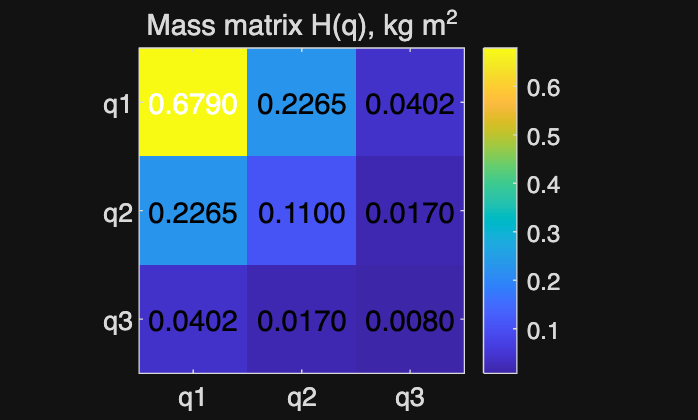

figure; imagesc(H); axis image; colormap(parula); colorbar;
set(gca,'XTick',1:3,'YTick',1:3,'XTickLabel',{'q1','q2','q3'},'YTickLabel',{'q1','q2','q3'});
for i=1:3
    for j=1:3
        if H(i,j)>0.5*max(H(:)), col='w'; else, col='k'; end
        text(j,i,sprintf('%.4f',H(i,j)),'HorizontalAlignment','center','Color',col);
    end
end
title('Mass matrix H(q), kg m^2');

## 19｜重力项：支撑力矩的符号


$$g(q)=\frac{\partial U}{\partial q}=\sum_i m_i g_0 J_{vi}^{y\,T}.$$


动力学约定为 $H\ddot q+c+g=\tau$。因此无驱动力矩时，重力导致的加速度是 $-H^{-1}g$；要静止支撑，则需 $\tau=g(q)$。`gravity_vector(P,q)` 返回的是方程左侧的重力项，也就是静态补偿力矩，**不是重力本身施加的广义力** $-g$。

零位所有杆水平向右，重力想让杆顺时针落下，因此正向支撑力矩应为正。全部竖直向上时，理想模型中重力力矩为零，但这个平衡是失稳的。

**检查**：势能梯度、质心重力虚功和零位手算支撑力矩。**练习**：把 $q_1=-90^\circ$，其余为零，比较与竖直向上状态的势能和稳定性。

**对应函数**：gravity_vector（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; h=1e-6; E3=eye(3); g=gravity_vector(P,q); gradU=zeros(3,1);
for j=1:3
    e=h*E3(:,j); gradU(j)=(potential(P,q+e)-potential(P,q-e))/(2*h);
end
assert(norm(g-gradU)<1e-8);
[~,Jv,~]=com_data(P,q); Qgravity=zeros(3,1);
for i=1:3, Qgravity=Qgravity+Jv(:,:,i).'*[0;-P.m(i)*P.g0;0]; end
assert(norm(Qgravity+g)<1e-12);
l=P.l; m=P.m; lc=P.lc;
g_home_hand=P.g0*[m(1)*lc(1)+m(2)*(l(1)+lc(2))+m(3)*(l(1)+l(2)+lc(3));...
                  m(2)*lc(2)+m(3)*(l(2)+lc(3));m(3)*lc(3)];
assert(norm(gravity_vector(P,zeros(3,1))-g_home_hand)<1e-12);
assert(norm(gravity_vector(P,[pi/2;0;0]))<1e-12);
disp('g(q_demo), Nm:'); disp(g.'); disp('home support torque, Nm:'); disp(g_home_hand.');

g(q_demo), Nm:
       11.529       3.5432       0.4162

home support torque, Nm:
       13.047       3.8259       0.5886



assert(norm(g_home_hand-[13.0473;3.8259;0.5886])<1e-10);


## 20｜质量矩阵导数：先差分，再用解析导数加速

科氏项需要 $\partial H/\partial q_k$。最容易对应公式的版本是中心差分：


$$\frac{\partial H}{\partial q_k}\approx\frac{H(q+h e_k)-H(q-h e_k)}{2h}.$$


为了让 电脑 后续积分少做重复计算，再实现本平面模型的解析导数。$J_{vi,j}$ 每一项是 $[-d\sin\alpha_a,d\cos\alpha_a,0]^T$，对能影响 $\alpha_a$ 的 $q_k$ 求导，变成 $[-d\cos\alpha_a,-d\sin\alpha_a,0]^T$。进而


$$\partial_k H=\sum_i m_i\left((\partial_kJ_{vi})^TJ_{vi}+J_{vi}^T\partial_kJ_{vi}\right).$$


本模型的角速度雅可比和 $I_{zi}$ 是常量，所以旋转动能部分导数为零。`dH(i,j,k)` 的第三个下标是求导关节。

**练习**：比较 $h=10^{-2},10^{-5},10^{-9}$ 的差分误差，观察截断误差与舍入误差的折衷。

**对应函数**：mass_derivatives_fd、mass_derivatives（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dH_exact=mass_derivatives(P,q);
for h=[1e-2 1e-5 1e-9]
    dH_fd=mass_derivatives_fd(P,q,h); err=norm(dH_fd(:)-dH_exact(:));
    fprintf('h=%.0e, derivative error=%.3e\n',h,err);
end

h=1e-02, derivative error=3.827e-06
h=1e-05, derivative error=1.778e-11
h=1e-09, derivative error=1.162e-07


dH_fd=mass_derivatives_fd(P,q);
assert(norm(dH_fd(:)-dH_exact(:))<1e-8);
assert(norm(dH_exact(:,:,1),'fro')<1e-12);
disp('H does not depend on global planar rotation q1: PASS');

H does not depend on global planar rotation q1: PASS


## 21｜科氏与离心项：Christoffel 符号


$$\Gamma_{ijk}=\frac12\left(\frac{\partial H_{ij}}{\partial q_k}
+\frac{\partial H_{ik}}{\partial q_j}-\frac{\partial H_{jk}}{\partial q_i}\right),\qquad
C_{ij}=\sum_k\Gamma_{ijk}\dot q_k,\quad c=C\dot q.$$


$c$ 是进入运动方程的三维力矩向量，既包含速度乘积项，也包含速度平方项。$C$ 的表示不唯一；本教程固定使用上述 Christoffel 构造。不要把矩阵 $C$ 和向量 $c$ 混用。

关键检查：$c(q,0)=0$，$c(q,2\dot q)=4c(q,\dot q)$，以及


$$\dot H-2C\ \text{为反对称矩阵},\qquad
\dot H=\sum_k(\partial_kH)\dot q_k.$$


这个恒等式联系着动能与功率平衡，比只观察一个数值更有说服力。

**对应函数**：coriolis_matrix、coriolis_vector（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3];
C=coriolis_matrix(P,q,dq); c=coriolis_vector(P,q,dq);
dH=mass_derivatives_fd(P,q); Hdot=zeros(3);
for k=1:3, Hdot=Hdot+dH(:,:,k)*dq(k); end
A=Hdot-2*C;
assert(norm(A+A.','fro')<1e-8);
assert(norm(coriolis_vector(P,q,zeros(3,1)))<1e-12);
assert(norm(coriolis_vector(P,q,2*dq)-4*c)<1e-12);
assert(norm(coriolis_vector(P,q,-dq)-c)<1e-12);
disp('C ='); disp(C); disp('c = C*dq (Nm):'); disp(c.');

C =
    -0.023965     0.010885      -0.0109
    -0.039527   -0.0046765   -0.0077942
    0.0056024    0.0031177   9.7145e-19

c = C*dq (Nm):
    -0.015033    -0.017214    0.0016174



fprintf('skew-symmetry residual = %.3e\n',norm(A+A.','fro'));

skew-symmetry residual = 5.286e-12


## 22｜逆动力学、正动力学与外力

拉格朗日方程


$$\frac{d}{dt}\frac{\partial L}{\partial\dot q_i}-\frac{\partial L}{\partial q_i}=\tau_i$$


整理为


$$H(q)\ddot q+c(q,\dot q)+g(q)=\tau.$$


**逆动力学**：给定 $q,\dot q,\ddot q$ 求 $\tau$。**正动力学**：给定状态与力矩，解线性方程


$$\ddot q=\operatorname{solve}(H,\tau-c-g).$$


没有外力时，$\tau$ 是驱动关节力矩。有末端环境外力时：


$$H\ddot q+c+g=\tau_{motor}+J_p^Tf_{env}.$$


所以静态支撑电机力矩为 $\tau_{motor}=g-J_p^Tf_{env}$。下面先验证正逆动力学闭环、重力补偿平衡和一阶瞬时功率。


$$\dot E=\dot q^T\tau\quad\text{（无摩擦、无外力）}.$$


**对应函数**：inverse_dynamics、forward_dynamics（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q=P.qdemo; dq=[0.4;-0.2;0.3]; ddq=[0.2;0.3;-0.1];
tau=inverse_dynamics(P,q,dq,ddq);
assert(norm(forward_dynamics(P,q,dq,tau)-ddq)<1e-10);
assert(norm(forward_dynamics(P,q,zeros(3,1),gravity_vector(P,q)))<1e-12);
h=1e-6;
Ep=kinetic(P,q+h*dq,dq+h*ddq)+potential(P,q+h*dq);
Em=kinetic(P,q-h*dq,dq-h*ddq)+potential(P,q-h*dq);
assert(abs((Ep-Em)/(2*h)-dq.'*tau)<1e-7);
f_env=[0;-2;0]; tau_motor=gravity_vector(P,q)-jac_point(P,q).'*f_env;
ddq_static=forward_dynamics(P,q,zeros(3,1),tau_motor+jac_point(P,q).'*f_env);
assert(norm(ddq_static)<1e-10);
disp('inverse dynamics tau (Nm):'); disp(tau.');

inverse dynamics tau (Nm):
       11.714       3.6026      0.43016



disp('forward dynamics ddq (rad/s^2):'); disp(forward_dynamics(P,q,dq,tau).');

forward dynamics ddq (rad/s^2):
          0.2          0.3         -0.1



disp('static motor torque with external force:'); disp(tau_motor.');

static motor torque with external force:
       13.084       4.4056      0.69905



## 23｜再走一条路径：直接验证 Euler–Lagrange

只检查“逆动力学再送入正动力学”可能漏掉两者共有的错误。这里以独立质心动能 `kinetic` 和势能 `potential` 为起点，数值计算


$$\tau_{EL}=\frac{d}{dt}(H\dot q)-\nabla_qK+\nabla_qU.$$


在 $t\pm h$ 使用 $q(t\pm h)=q\pm h\dot q+\frac12h^2\ddot q$、$\dot q(t\pm h)=\dot q\pm h\ddot q$。对 $K,U$ 分别做构型方向差分；动量也从质心速度求和得到。这条检查不使用解析 Christoffel 导数。

差分误差通常比代数检查大，因此允许 $10^{-6}$ 量级容差。**练习**：故意改错 $\Gamma_{ijk}$ 的一个下标，观察本节是否能检测到错误。

**对应函数**：momentum_com（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); rng(23); errors=zeros(12,1); E3=eye(3); h=1e-5;
for sample=1:12
    q=2*rand(3,1)-1; dq=2*rand(3,1)-1; ddq=2*rand(3,1)-1;
    qp=q+h*dq+0.5*h*h*ddq; qm=q-h*dq+0.5*h*h*ddq;
    dMomentum=(momentum_com(P,qp,dq+h*ddq)-momentum_com(P,qm,dq-h*ddq))/(2*h);
    gradK=zeros(3,1); gradU=zeros(3,1);
    for j=1:3
        e=h*E3(:,j);
        gradK(j)=(kinetic(P,q+e,dq)-kinetic(P,q-e,dq))/(2*h);
        gradU(j)=(potential(P,q+e)-potential(P,q-e))/(2*h);
    end
    tau_EL=dMomentum-gradK+gradU;
    errors(sample)=norm(tau_EL-inverse_dynamics(P,q,dq,ddq));
end
assert(max(errors)<1e-6);
fprintf('12 independent Euler-Lagrange checks: max error=%.3e Nm\n',max(errors));

12 independent Euler-Lagrange checks: max error=3.956e-10 Nm


## 24｜数值积分：从加速度走到运动轨迹

状态 $x=[q;\dot q]$，状态方程为


$$\dot x=f(t,x)=\begin{bmatrix}\dot q\\H(q)^{-1}(\tau-c-g)\end{bmatrix}.$$


最简单的显式 Euler 为 $x_{k+1}=x_k+\Delta t f(t_k,x_k)$，但能量容易漂移。这里使用经典四阶 Runge–Kutta（RK4）：


$$k_1=f(t,x),\quad k_2=f(t+h/2,x+hk_1/2),$$



$$k_3=f(t+h/2,x+hk_2/2),\quad k_4=f(t+h,x+hk_3),$$



$$x_{k+1}=x_k+\frac h6(k_1+2k_2+2k_3+k_4).$$


控制器在 RK4 每个子阶段重新计算，相当于连续反馈的数值近似；这不是具有固定采样/保持的离散控制器。`simulate` 返回时间、状态与采样时刻的力矩。`duration` 最好取 `dt` 的整数倍。

先释放没有电机力矩、没有阻尼的机械臂。图中关节角不做 wrap，保持连续。连杆可以穿过基座或彼此，本模型没有碰撞处理。

**练习**：把 `dt` 加倍，比较轨迹和能量，而不要只凭“画出来像摆动”判断积分正确。

**对应函数**：rk4_step、simulate、state_rhs（均在文末，可先读本节实验，再查看函数实现）。

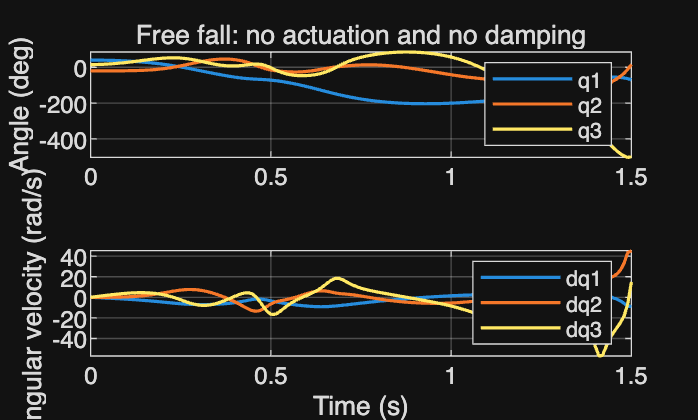

P=robot_model(); zero_torque=@(t,q,dq) zeros(3,1);
q0=[40;-20;15]*pi/180; dq0=zeros(3,1);
[ts,X,Tau]=simulate(P,zero_torque,q0,dq0,1.5,0.01);
figure;
subplot(2,1,1); plot(ts,X(:,1:3)*180/pi,'LineWidth',1.2); grid on;
ylabel('Angle (deg)'); title('Free fall: no actuation and no damping'); legend('q1','q2','q3');
subplot(2,1,2); plot(ts,X(:,4:6),'LineWidth',1.2); grid on;
xlabel('Time (s)'); ylabel('Angular velocity (rad/s)'); legend('dq1','dq2','dq3');

disp('final angles (deg):'); disp(X(end,1:3)*180/pi);

final angles (deg):
      -69.432       15.211      -501.09



## 25｜能量守恒与步长收敛：检验积分器

理想无驱动、无摩擦系统满足 $E=K+U=\text{常量}$。数值积分器只能近似保持：


$$\epsilon_E(t)=\frac{E(t)-E(0)}{\max(|E(0)|,1\,\mathrm J)}.$$


下面比较 Euler 与 RK4，并把 RK4 步长减半。Euler 一阶、RK4 四阶，但 RK4 **不是能量严格守恒或辛积分器**；短时间、光滑问题通常随步长减小明显改善，不保证长时间能量不漂移。

以更小步长的 RK4 末状态作参考只是数值收敛检查，并不是精确解。默认测试只跑短时间，避免在 电脑 上等待过久。

**练习**：延长到 5 s；观察同一控制增益下步长与稳定性、耗时的关系。

**对应函数**：run_free、rk4_step（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); q0=[40;-20;15]*pi/180; dq0=zeros(3,1); duration=0.8;
dts=[0.01 0.01 0.005]; methods={'Euler','RK4','RK4'};
labels={'Euler 0.01','RK4 0.01','RK4 0.005'}; drifts=zeros(3,1); endpoints=zeros(6,3);
figure;
for k=1:3
    [ts,X,E]=run_free(P,q0,dq0,duration,dts(k),methods{k});
    relative=(E-E(1))/max(abs(E(1)),1);
    drifts(k)=max(abs(relative)); endpoints(:,k)=X(end,:).';
    fprintf('%s max normalized energy drift = %.6g\n',labels{k},drifts(k));
    if k==1
        subplot(2,1,1); plot(ts,relative,':','Color',P.colors(2,:),'LineWidth',1.5); grid on;
        ylabel('Signed normalized drift'); title('Euler energy drift'); legend(labels{k});
    else
        subplot(2,1,2); hold on;
        semilogy(ts(2:end),max(abs(relative(2:end)),1e-16),'LineWidth',1.3,'DisplayName',labels{k});
    end
end

Euler 0.01 max normalized energy drift = 0.267501
RK4 0.01 max normalized energy drift = 3.83918e-05
RK4 0.005 max normalized energy drift = 2.56485e-06


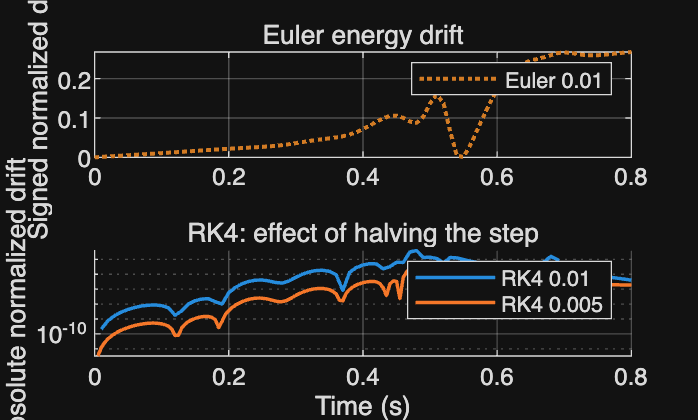

subplot(2,1,2); set(gca,'YScale','log'); hold off; grid on; legend('show');
xlabel('Time (s)'); ylabel('Absolute normalized drift'); title('RK4: effect of halving the step');

[~,Xref,~]=run_free(P,q0,dq0,duration,0.0025,'RK4');
err_coarse=norm(endpoints(:,2)-Xref(end,:).'); err_fine=norm(endpoints(:,3)-Xref(end,:).');
assert(drifts(3)<drifts(2) && drifts(2)<drifts(1) && err_fine<err_coarse);
fprintf('state errors, coarse/fine: %.6g / %.6g\n',err_coarse,err_fine);

state errors, coarse/fine: 0.00129178 / 6.3283e-05


## 26｜定点 PD 与重力补偿：为什么会有静差

给定常数目标 $q_d$：


$$\tau_{PD}=K_p(q_d-q)-K_d\dot q,$$



$$\tau_{PD+g}=K_p(q_d-q)-K_d\dot q+g(q).$$


PD 的位置误差需要产生支撑力矩，平衡时大致有 $K_p(q_d-q)=g(q)$，因此一般存在静差。加上准确重力补偿后，目标处 $e=0,\dot q=0$ 就能提供所需力矩。

$K_p$ 单位为 N·m/rad，$K_d$ 为 N·m·s/rad，下面使用逐关节对角增益。先在**目标状态**检查加速度，再做有限时长仿真。短时仿真末误差不等于严格稳态误差。

**练习**：降低 `Kp`，比较未补偿 PD 的误差；把补偿乘以 0.8，观察模型偏差影响。

**对应函数**：gravity_vector、simulate（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); qd=[30;-40;35]*pi/180; Kp=[35;12;2]; Kd=[3;1;0.1];
pd=@(t,q,dq) Kp.*(qd-q)-Kd.*dq;
pdg=@(t,q,dq) Kp.*(qd-q)-Kd.*dq+gravity_vector(P,q);
disp('acceleration at exact target, PD:'); disp(forward_dynamics(P,qd,zeros(3,1),pd(0,qd,zeros(3,1))).');

acceleration at exact target, PD:
      -20.157       1.5931        46.34



assert(norm(forward_dynamics(P,qd,zeros(3,1),pdg(0,qd,zeros(3,1))))<1e-10);
q0=qd+[-12;10;-8]*pi/180; dq0=zeros(3,1); labels={'PD','PD+g'}; controls={pd,pdg}; styles={'--','-'};
figure;
for k=1:2
    [ts,X,~]=simulate(P,controls{k},q0,dq0,2,0.005);
    errors=qd.'-X(:,1:3);
    for j=1:3
        subplot(3,1,j); hold on;
        plot(ts,errors(:,j)*180/pi,styles{k},'LineWidth',1.3,'DisplayName',labels{k});
        ylabel(sprintf('e%d (deg)',j)); grid on;
    end
    fprintf('%s finite-time final error (deg): ',labels{k}); disp(errors(end,:)*180/pi);
end

PD finite-time final error (deg):        18.958       13.212       14.584

PD+g finite-time final error (deg):     -0.029039    -0.027946     0.077179



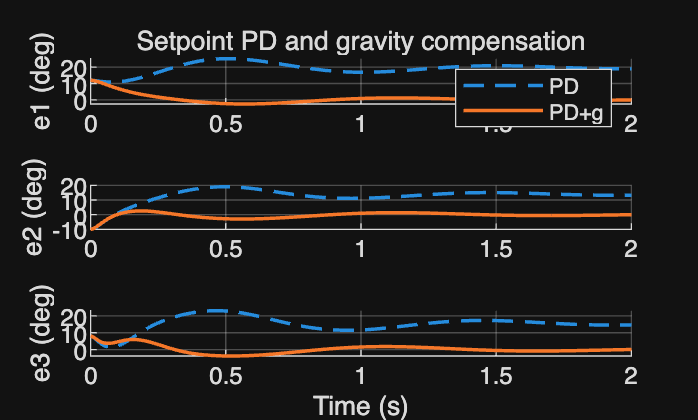

subplot(3,1,1); title('Setpoint PD and gravity compensation'); legend('show');
subplot(3,1,3); xlabel('Time (s)');

## 27｜轨迹与计算力矩控制：把动力学耦合补偿掉

给定光滑关节轨迹及其**解析速度、加速度**：


$$q_d=q_{off}+A\sin(\nu t),\quad\dot q_d=A\nu\cos(\nu t),\quad
\ddot q_d=-A\nu^2\sin(\nu t).$$


这里 $\nu$ 单位 rad/s，不是 Hz；若用 Hz，应乘 $2\pi$。

令 $e=q_d-q$，计算力矩控制采用


$$a=\ddot q_d+k_d(\dot q_d-\dot q)+k_p(q_d-q),$$



$$\tau=H(q)a+c(q,\dot q)+g(q).$$


模型完全准确、无饱和时 $\ddot q=a$，所以


$$\ddot e+k_d\dot e+k_pe=0.$$


这时 $k_p$ 单位 s⁻²，$k_d$ 单位 s⁻¹，与直接输出力矩的 PD 增益单位不同。选 $k_p=\omega_n^2,k_d=2\zeta\omega_n$；默认 $\omega_n=6\,\mathrm{s^{-1}},\zeta=1$。

先检查一个任意状态下，实际正动力学给出的加速度是否等于所构造的 $a$。**练习**：删掉 $c$，提高目标速度，比较跟踪变化。

**对应函数**：reference、control_torque（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); t=0.7; q=P.qdemo; dq=[0.4;-0.2;0.3];
[qd,dqd,ddqd]=reference(t); kp=36*ones(3,1); kd=12*ones(3,1);
a=ddqd+kp.*(qd-q)+kd.*(dqd-dq);
tau=mass_matrix(P,q)*a+coriolis_vector(P,q,dq)+gravity_vector(P,q);
assert(norm(tau-control_torque(P,'CT',t,q,dq))<1e-12);
assert(norm(forward_dynamics(P,q,dq,tau)-a)<1e-10);
h=1e-4; [qdp,dqdp,~]=reference(t+h); [qdm,dqdm,~]=reference(t-h);
assert(norm((qdp-qdm)/(2*h)-dqd)<1e-8);
assert(norm((dqdp-dqdm)/(2*h)-ddqd)<1e-8);
disp('reference q,dq,ddq:'); disp([qd dqd ddqd]);

reference q,dq,ddq:
      0.57126      0.16019     -0.13492
     -0.47307      0.13925     -0.23287
       0.5105     0.094639    -0.047467



disp('command / actual acceleration:'); disp([a forward_dynamics(P,q,dq,tau)]);

command / actual acceleration:
       -1.297       -1.297
       15.082       15.082
      -21.833      -21.833



disp('CT torque (Nm):'); disp(tau.');

CT torque (Nm):
       13.173         4.52      0.44744



## 28｜同一条轨迹，对比 PD、PD+g、计算力矩

使用相同初始状态、参考轨迹与积分方法，对比三种控制器。三者使用各自说明的增益，**增益没有做最优化，因此这不是算法优劣的公平性能排名**；本实验展示重力项、惯性前馈和耦合补偿的作用。

记录每个关节误差、驱动力矩与总误差范数。计算全时段角度 RMSE 与后半时段 RMSE，避免把初始误差与持续跟踪误差混为一谈。所有方法均使用同一理想模型，无噪声、无延迟、无力矩限幅。

**检查**：计算力矩控制的误差应与理论方程一致，最后误差显著小于初始误差。图中力矩仍以 N·m 展示，而不是用缩放后的视觉曲线代替实际力矩。

控制器增益集中在末尾 `control_torque` 函数中；每一种控制器在本节使用同一初始状态。

**对应函数**：control_torque、simulate（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); [qd0,~,~]=reference(0); q0=qd0+[-15;12;-10]*pi/180; dq0=zeros(3,1);
modes={'PD','PD+g','CT'}; styles={':','--','-'}; results=cell(3,1);
for k=1:3
    mode=modes{k}; controller=@(t,q,dq) control_torque(P,mode,t,q,dq);
    [ts,X,Tau]=simulate(P,controller,q0,dq0,2.5,0.005);
    Qd=zeros(numel(ts),3); for i=1:numel(ts), Qd(i,:)=reference(ts(i)).'; end
    e=Qd-X(:,1:3); mid=floor(size(e,1)/2)+1;
    rmse_all=sqrt(mean(e.^2,1))*180/pi; rmse_late=sqrt(mean(e(mid:end,:).^2,1))*180/pi;
    fprintf('%s all-time RMSE (deg): ',mode); disp(rmse_all);
    disp('late-half RMSE (deg):'); disp(rmse_late); disp('peak |tau| (Nm):'); disp(max(abs(Tau),[],1));
    results{k}=struct('ts',ts,'X',X,'Tau',Tau,'e',e);
end

PD all-time RMSE (deg):        19.969       15.651       16.137



late-half RMSE (deg):
       19.979       16.167       16.367

peak |tau| (Nm):
        15.84        4.358      0.77577



PD+g all-time RMSE (deg):         3.375       2.3838       3.2863



late-half RMSE (deg):
      0.67516      0.77535      0.89788

peak |tau| (Nm):
       22.615       5.5042      0.99944



CT all-time RMSE (deg):        4.5825       3.2355       3.0241



late-half RMSE (deg):
     0.021842     0.013114     0.014253

peak |tau| (Nm):
       20.881       6.5731       1.1137



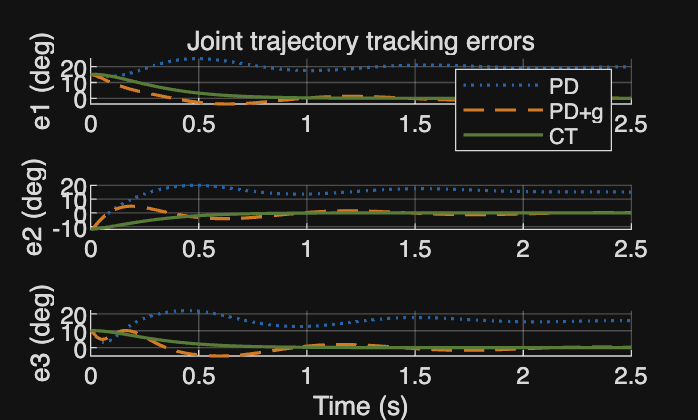

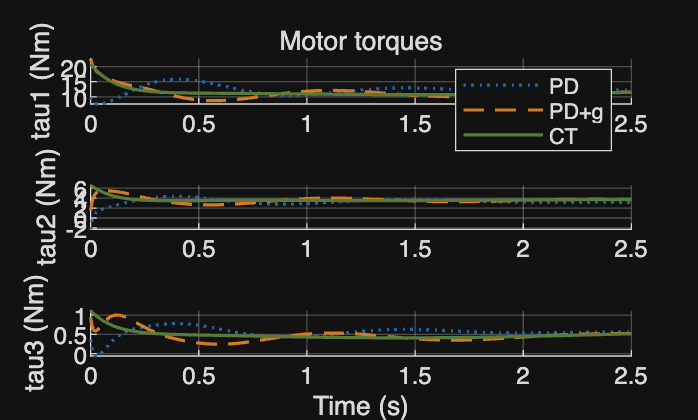

assert(norm(results{3}.e(end,:))<0.01*norm(results{3}.e(1,:)));
for whichplot=1:2
    figure;
    for j=1:3
        subplot(3,1,j); hold on;
        for k=1:3
            r=results{k};
            if whichplot==1, y=r.e(:,j)*180/pi; else, y=r.Tau(:,j); end
            plot(r.ts,y,styles{k},'Color',P.colors(k,:),'LineWidth',1.2,'DisplayName',modes{k});
        end
        hold off; grid on;
        if whichplot==1, ylabel(sprintf('e%d (deg)',j)); else, ylabel(sprintf('tau%d (Nm)',j)); end
    end
    subplot(3,1,1); legend('show');
    if whichplot==1, title('Joint trajectory tracking errors'); else, title('Motor torques'); end
    subplot(3,1,3); xlabel('Time (s)');
end

## 29｜给计算力矩加限幅：理想误差方程何时失效

实际驱动有力矩上限。这里仅加入


$$\tau_{applied}=\operatorname{clip}(\tau_{CT},-\tau_{max},\tau_{max}).$$


一旦发生限幅，$\ddot q=a$ 不再成立，理想二阶误差方程也不再成立。与无限幅计算力矩对比时，保持其他条件相同。本节不是电机、减速器或真实伺服系统模型。

**练习**：把限幅从每关节 3 N·m 调到 `[15, 5, 2]`，思考第一关节支撑整条手臂所需力矩为什么更大。也可在控制器中把 $H,c,g$ 乘以 0.8，模拟简单整体模型失配；保持正动力学模型不变。

**对应函数**：control_torque、simulate（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); [qd0,~,~]=reference(0); q0=qd0+[-15;12;-10]*pi/180; dq0=zeros(3,1);
limit=[3;3;3]; labels={'Ideal CT','Limited CT'}; styles={'-','--'};
figure;
for k=1:2
    if k==1, lim=[]; else, lim=limit; end
    controller=@(t,q,dq) control_torque(P,'CT',t,q,dq,lim);
    [ts,X,Tau]=simulate(P,controller,q0,dq0,1.5,0.005);
    Qd=zeros(numel(ts),3); for i=1:numel(ts), Qd(i,:)=reference(ts(i)).'; end
    errors=sqrt(sum((Qd-X(:,1:3)).^2,2))*180/pi;
    subplot(2,1,1); hold on; plot(ts,errors,styles{k},'DisplayName',labels{k},'LineWidth',1.3);
    subplot(2,1,2); hold on; plot(ts,Tau(:,1),styles{k},'DisplayName',labels{k},'LineWidth',1.3);
    fprintf('%s final error norm (deg): %.4f\n',labels{k},errors(end));
    if k==2, assert(all(all(abs(Tau)<=limit.'+1e-12))); end
end

Ideal CT final error norm (deg): 0.0277
Limited CT final error norm (deg): 130.3194


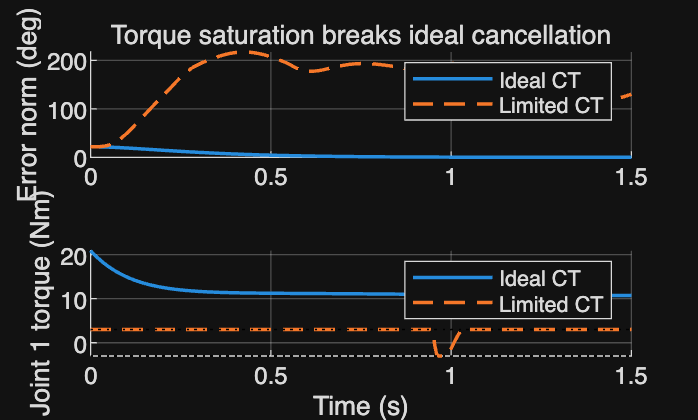

subplot(2,1,1); hold off; grid on; ylabel('Error norm (deg)');
title('Torque saturation breaks ideal cancellation'); legend('show');
subplot(2,1,2); plot([0 ts(end)],[limit(1) limit(1)],'k:'); plot([0 ts(end)],[-limit(1) -limit(1)],'k:');
hold off; grid on; xlabel('Time (s)'); ylabel('Joint 1 torque (Nm)');
legend(labels);

## 30｜集中自检与下一步练习

本节可以直接独立运行，集中检查以下链路：

1. POE 与独立几何位姿；空间/刚体雅可比与变换原始定义。

2. 末端、质心真实速度与位置差分。

3. 动能二次型、质量矩阵正定、势能梯度、质量矩阵解析导数。

4. $\dot H-2C$ 反对称、正逆动力学、独立 Euler–Lagrange 与功率平衡。

5. 计算力矩的加速度补偿等式。

每个检查的容差对应双精度计算与中心差分精度；`PASS` 代表这些已覆盖的恒等式在抽样状态通过，不是对所有实现的数学证明。能量积分与控制时域检验另见 25、28 节，避免在这里再次执行耗时仿真。

建议按顺序做小项目：

• **A｜换坐标系**：把末端刚体系旋转 $30^\circ$、原点移到第三关节，分别验证 $B_i,J_b$ 与真实末端速度。

• **B｜换质量**：给第三杆加质量。若作为杆本身的均匀增重，更新 $m_3,I_{z3}$；若作为末端点载荷，单独加入 $m_pJ_p^TJ_p$ 和 $m_pg_0y_{tip}$，不要混成均匀杆。

• **C｜加阻尼**：将动力学右侧改成 $\tau-D\dot q$。无驱动时应满足 $\dot E=-\dot q^TD\dot q\le0$，重新做能量检查。

• **D｜从点到轨迹**：用位置 IK 求多个目标点；关注初值连续性，再构造平滑关节轨迹，使用解析或一致的差分速度/加速度进行控制。

• **E｜单摆退化核验**：锁死关节 2、3 后，求系统关于基座的等效惯量与重力力矩。注意“锁死”是约束 $\ddot q_2=\ddot q_3=0$，不能靠令后两个电机力矩为零来代替。

### 常见问题速查

现象 ｜ 先检查什么

`v_s` 不等于末端位置差分 ｜ 需要加 $\omega_s\times p$

固定刚体点坐标不变却有速度 ｜ 坐标导数与真实速度表达不同

改原点后 POE 与旧末端不一致 ｜ $T$ 描述新原点；用固定局部坐标重建旧末端

三根杆竖直时 $g=0$ ｜ 重力作用线穿过转轴，不能据此判断稳定性

PD+g 轨迹仍有误差 ｜ 只补偿重力，没有完整惯性/科氏前馈

增大增益后仿真发散 ｜ 显式积分步长可能不适合更快的闭环动态

逆解失败 ｜ 目标可达性、初值、奇异性、阻尼、任务尺度

修改上一节参数没有影响下一节 ｜ 每个单元有自己的默认参数，需要在本节重新修改

至此，你已有一套可以逐行追溯公式的三连杆运动学、动力学与控制实现。后续可以扩展到轨迹规划、约束控制、载荷辨识和多自由度三维机器人。

**对应函数**：self_check（均在文末，可先读本节实验，再查看函数实现）。

P=robot_model(); worst=self_check(P,20);

pose                 max residual = 4.194e-16 : PASS
twist                max residual = 1.432e-10 : PASS
tip velocity         max residual = 3.831e-11 : PASS
COM velocity         max residual = 3.933e-11 : PASS
gravity gradient     max residual = 3.188e-10 : PASS
dH                   max residual = 2.295e-11 : PASS
skew symmetry        max residual = 2.370e-11 : PASS
Euler-Lagrange       max residual = 3.222e-10 : PASS
power                max residual = 1.606e-10 : PASS
20 random states: all checks PASS


% 独立参考值：零位静态支撑力矩。
assert(norm(gravity_vector(P,zeros(3,1))-[13.0473;3.8259;0.5886])<1e-10);
% 独立参考值：默认构型的末端位置与朝向。
T=fk_space(P,P.qdemo);
expected=[0.7776092656378055;0.2637756427065533;0];
assert(norm(T(1:3,4)-expected)<1e-10);
assert(abs(atan2(T(2,1),T(1,1))-pi/4)<1e-12);
disp('固定参考值与随机恒等式检查全部通过。');

固定参考值与随机恒等式检查全部通过。


## 可选参考资料（运行不依赖这些链接）

本文件为三连杆教学实例，推导与代码均在本文件内。旋量、POE、雅可比和控制的术语与 Kevin M. Lynch、Frank C. Park 的《Modern Robotics》相衔接；下列为作者的官方教学页面，并非代码库依赖。

• 刚体雅可比与空间/刚体雅可比的伴随关系（https://modernrobotics.northwestern.edu/nu-gm-book-resource/5-1-2-body-jacobian/）

• 拉格朗日动力学、速度乘积项与 Christoffel 符号（https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-1-lagrangian-formulation-of-dynamics-part-2-of-2/）

• 力矩输入的运动控制与计算力矩控制（https://modernrobotics.northwestern.edu/nu-gm-book-resource/11-4-motion-control-with-torque-or-force-inputs-part-3-of-3/）

可在有网络时作为后续拓展阅读；离线学习时直接跳过。

## 局部函数：把公式落实为 MATLAB

以下函数是本文件的一部分。阅读某节时，可按该节的「对应函数」定位。所有函数显式接收参数 P，不依赖全局变量。

function P = robot_model()
% 模型参数集中在此；各节重新建立 P，修改只影响当前节。
P.l = [0.4;0.3;0.2];
P.m = [1.5;1.0;0.6];
P.lc = P.l/2;
P.Izz = P.m.*P.l.^2/12;
P.g0 = 9.81;
P.qdemo = [30;-45;60]*pi/180;
P.colors = [0.1412 0.3882 0.6510;0.8235 0.4824 0.1412;0.3490 0.4824 0.2196];
end

function pts = joint_points(P,q)
% 每一列是一个空间点：基座、关节2、关节3、末端。
alpha = cumsum(q(:));
d = [P.l.*cos(alpha),P.l.*sin(alpha),zeros(3,1)].';
pts = [zeros(3,1),cumsum(d,2)];
end

function R = rotz3(phi)
R = [cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1];
end

function T = fk_geom(P,q,phi0)
if nargin<3, phi0=0; end
pts = joint_points(P,q);
T = [rotz3(sum(q)+phi0),pts(:,end);0 0 0 1];
end

function draw_arm(P,q)
pts = joint_points(P,q);
plot(pts(1,:),pts(2,:),'o-','LineWidth',3,'Color',P.colors(1,:));
hold on; plot(0,0,'ks','MarkerSize',8); hold off;
axis equal; xlim([-1 1]); ylim([-1 1]); grid on;
xlabel('x (m)'); ylabel('y (m)');
end

function W = skew3(w)
w = w(:);
W = [0 -w(3) w(2);w(3) 0 -w(1);-w(2) w(1) 0];
end

function w = vee3(W)
w = [W(3,2);W(1,3);W(2,1)];
end

function X = hat6(V)
X = [skew3(V(1:3)),V(4:6);0 0 0 0];
end

function V = vee6(X)
V = [vee3(X(1:3,1:3));X(1:3,4)];
end

function Ti = invT(T)
R = T(1:3,1:3); p = T(1:3,4);
Ti = [R.' -R.'*p;0 0 0 1];
end

function A = adjointT(T)
R = T(1:3,1:3); p = T(1:3,4);
A = [R zeros(3);skew3(p)*R R];
end

function [M,Slist,Blist] = home_axes(P,phi0,p0)
if nargin<2, phi0=0; end
if nargin<3, p0=[sum(P.l);0;0]; end
M = [rotz3(phi0),p0(:);0 0 0 1];
ri = [0 P.l(1) P.l(1)+P.l(2);zeros(2,3)];
wi = [0;0;1]; Slist = zeros(6,3);
for i=1:3
    Slist(:,i) = [wi;-cross(wi,ri(:,i))];
end
Blist = adjointT(invT(M))*Slist;
end

function T = exp_twist(S,theta)
% 单位转动轴或纯移动轴的 SE(3) 指数；不需要第三方工具箱。
w = S(1:3); v = S(4:6); T = eye(4); wn = norm(w);
if wn<1e-14
    T(1:3,4)=theta*v;
    return
end
assert(abs(wn-1)<1e-10,'转动轴必须满足 norm(w)=1。');
W = skew3(w);
if abs(theta)<1e-4
    a = theta*(1-theta^2/6+theta^4/120-theta^6/5040);
    b = theta^2/2*(1-theta^2/12+theta^4/360);
    c = theta^3/6*(1-theta^2/20+theta^4/840);
else
    a = sin(theta); b = 2*sin(theta/2)^2; c = theta-sin(theta);
end
T(1:3,1:3) = eye(3)+a*W+b*(W*W);
G = theta*eye(3)+b*W+c*(W*W);
T(1:3,4) = G*v;
end

function T = fk_space(P,q,phi0,p0)
if nargin<3, phi0=0; end
if nargin<4, p0=[sum(P.l);0;0]; end
[M,Slist,~] = home_axes(P,phi0,p0);
T = eye(4);
for i=1:3, T=T*exp_twist(Slist(:,i),q(i)); end
T = T*M;
end

function T = fk_body(P,q,phi0,p0)
if nargin<3, phi0=0; end
if nargin<4, p0=[sum(P.l);0;0]; end
[M,~,Blist] = home_axes(P,phi0,p0);
T = M;
for i=1:3, T=T*exp_twist(Blist(:,i),q(i)); end
end

function Js = jac_space(P,q)
[~,Slist,~] = home_axes(P);
Js = zeros(6,3); Tprev = eye(4);
for i=1:3
    Js(:,i) = adjointT(Tprev)*Slist(:,i);
    Tprev = Tprev*exp_twist(Slist(:,i),q(i));
end
end

function Jb = jac_body(P,q,phi0,p0)
if nargin<3, phi0=0; end
if nargin<4, p0=[sum(P.l);0;0]; end
[~,~,Blist] = home_axes(P,phi0,p0);
Jb = zeros(6,3); Ttail = eye(4);
for i=3:-1:1
    Jb(:,i) = adjointT(Ttail)*Blist(:,i);
    Ttail = Ttail*exp_twist(Blist(:,i),-q(i));
end
end

function Jp = jac_point(P,q)
T = fk_space(P,q); p = T(1:3,4); Js = jac_space(P,q);
Jp = -skew3(p)*Js(1:3,:)+Js(4:6,:);
end

function a = wrap_angle(a)
a = mod(a+pi,2*pi)-pi;
end

function J = jac_planar(P,q)
alpha = cumsum(q); J = zeros(3,3);
for j=1:3
    J(1,j) = -sum(P.l(j:3).*sin(alpha(j:3)));
    J(2,j) =  sum(P.l(j:3).*cos(alpha(j:3)));
end
J(3,:)=1;
end

function e = ik_error(P,target,q,pose)
pts = joint_points(P,q); e = target(1:2)-pts(1:2,end);
if pose, e=[e;wrap_angle(target(3)-sum(q))]; end
end

function [q,success,history] = ik_dls(P,target,q0,pose)
if nargin<4, pose=false; end
q = q0(:); target=target(:); damping=0.02; maxIter=150;
if pose, W=diag([1 1 0.4]); else, W=eye(2); end
history = zeros(maxIter,1); success=false;
for k=1:maxIter
    e=ik_error(P,target,q,pose); J=jac_planar(P,q);
    if ~pose, J=J(1:2,:); end
    A=W*J; b=W*e; history(k)=norm(b);
    if norm(e(1:2))<1e-7 && (~pose || abs(e(3))<1e-7)
        success=true; history=history(1:k); return
    end
    step=A.'*((A*A.'+damping^2*eye(numel(b)))\b);
    step=step*min(1,0.25/max(norm(step),1e-15));
    accepted=false;
    for scale=[1 0.5 0.25 0.125 0.0625]
        qnew=q+scale*step; enew=ik_error(P,target,qnew,pose);
        if norm(W*enew)<norm(b)
            q=qnew; accepted=true; break
        end
    end
    if ~accepted, history=history(1:k); return; end
end
end

function [pc,Jv,Jw] = com_data(P,q)
pts=joint_points(P,q); alpha=cumsum(q);
pc=pts(:,1:3)+[P.lc.*cos(alpha),P.lc.*sin(alpha),zeros(3,1)].';
Jv=zeros(3,3,3); Jw=zeros(3,3,3); z=[0;0;1];
for i=1:3
    for j=1:i
        Jv(:,j,i)=cross(z,pc(:,i)-pts(:,j));
        Jw(:,j,i)=z;
    end
end
end

function K = kinetic(P,q,dq)
[~,Jv,Jw]=com_data(P,q); K=0;
for i=1:3
    vc=Jv(:,:,i)*dq; wc=Jw(:,:,i)*dq;
    K=K+0.5*P.m(i)*(vc.'*vc)+0.5*P.Izz(i)*wc(3)^2;
end
end

function U = potential(P,q)
[pc,~,~]=com_data(P,q); U=P.g0*(P.m.'*pc(2,:).');
end

function H = mass_matrix(P,q)
[~,Jv,Jw]=com_data(P,q); H=zeros(3);
for i=1:3
    Jwi=Jw(3,:,i);
    H=H+P.m(i)*(Jv(:,:,i).'*Jv(:,:,i))+P.Izz(i)*(Jwi.'*Jwi);
end
end

function g = gravity_vector(P,q)
[~,Jv,~]=com_data(P,q); g=zeros(3,1);
for i=1:3, g=g+P.m(i)*P.g0*Jv(2,:,i).'; end
end

function dH = mass_derivatives_fd(P,q,h)
if nargin<3, h=1e-5; end
E=eye(3); dH=zeros(3,3,3);
% MATLAB: dH(:,:,k)=partial H/partial q_k
for k=1:3
    e=E(:,k)*h;
    dH(:,:,k)=(mass_matrix(P,q+e)-mass_matrix(P,q-e))/(2*h);
end
end

function dH = mass_derivatives(P,q)
alpha=cumsum(q); [~,Jv,~]=com_data(P,q); dH=zeros(3,3,3);
for i=1:3
    for k=1:i
        dJ=zeros(3);
        for j=1:i
            for a=max(j,k):i
                if a==i, length=P.lc(i); else, length=P.l(a); end
                dJ(1:2,j)=dJ(1:2,j)-length*[cos(alpha(a));sin(alpha(a))];
            end
        end
        dH(:,:,k)=dH(:,:,k)+P.m(i)*(dJ.'*Jv(:,:,i)+Jv(:,:,i).'*dJ);
    end
end
end

function C = coriolis_matrix(P,q,dq)
dH=mass_derivatives(P,q); C=zeros(3);
for i=1:3
    for j=1:3
        for k=1:3
            Gamma_ijk=0.5*(dH(i,j,k)+dH(i,k,j)-dH(j,k,i));
            C(i,j)=C(i,j)+Gamma_ijk*dq(k);
        end
    end
end
end

function c = coriolis_vector(P,q,dq)
c=coriolis_matrix(P,q,dq)*dq;
end

function tau = inverse_dynamics(P,q,dq,ddq)
tau=mass_matrix(P,q)*ddq+coriolis_vector(P,q,dq)+gravity_vector(P,q);
end

function ddq = forward_dynamics(P,q,dq,tau)
ddq=mass_matrix(P,q)\(tau-coriolis_vector(P,q,dq)-gravity_vector(P,q));
end

function momentum = momentum_com(P,q,dq)
[~,Jv,Jw]=com_data(P,q); momentum=zeros(3,1);
for i=1:3
    Jwi=Jw(3,:,i);
    momentum=momentum+P.m(i)*Jv(:,:,i).'*(Jv(:,:,i)*dq)+P.Izz(i)*Jwi.'*(Jwi*dq);
end
end

function xnext = rk4_step(f,t,x,dt)
k1=f(t,x);
k2=f(t+dt/2,x+dt*k1/2);
k3=f(t+dt/2,x+dt*k2/2);
k4=f(t+dt,x+dt*k3);
xnext=x+dt*(k1+2*k2+2*k3+k4)/6;
end

function dx = state_rhs(P,controller,t,x)
q=x(1:3); dq=x(4:6); tau=controller(t,q,dq);
dx=[dq;forward_dynamics(P,q,dq,tau)];
end

function [ts,X,Tau] = simulate(P,controller,q0,dq0,duration,dt)
n=round(duration/dt); ts=(0:n).'*dt;
X=zeros(n+1,6); Tau=zeros(n+1,3); X(1,:)=[q0(:);dq0(:)].';
f=@(t,x) state_rhs(P,controller,t,x);
for k=1:n
    x=X(k,:).'; Tau(k,:)=controller(ts(k),x(1:3),x(4:6)).';
    xn=rk4_step(f,ts(k),x,dt); X(k+1,:)=xn.';
    assert(all(isfinite(xn)) && norm(xn)<1e5,'积分发散：请减小步长或控制增益。');
end
Tau(end,:)=controller(ts(end),X(end,1:3).',X(end,4:6).').';
end

function [qd,dqd,ddqd] = reference(t)
offset=[25;-35;25]*pi/180; amp=[12;10;8]*pi/180; freq=[1;1.3;0.8];
qd=offset+amp.*sin(freq*t);
dqd=amp.*freq.*cos(freq*t);
ddqd=-amp.*freq.^2.*sin(freq*t);
end

function tau = control_torque(P,mode,t,q,dq,limit)
if nargin<6, limit=[]; end
[qd,dqd,ddqd]=reference(t); e=qd-q; de=dqd-dq;
Kp=[35;12;2]; Kd=[3;1;0.1]; kp=[36;36;36]; kd=[12;12;12];
switch mode
    case 'PD'
        tau=Kp.*e+Kd.*de;
    case 'PD+g'
        tau=Kp.*e+Kd.*de+gravity_vector(P,q);
    case 'CT'
        a=ddqd+kp.*e+kd.*de;
        tau=mass_matrix(P,q)*a+coriolis_vector(P,q,dq)+gravity_vector(P,q);
    otherwise
        error('未知控制器类型。');
end
if ~isempty(limit), tau=max(-limit,min(limit,tau)); end
end

function [ts,X,E] = run_free(P,q0,dq0,duration,dt,method)
zero=@(t,q,dq) zeros(3,1);
n=round(duration/dt); ts=(0:n).'*dt; X=zeros(n+1,6); X(1,:)=[q0;dq0].';
f=@(t,x) state_rhs(P,zero,t,x);
for k=1:n
    x=X(k,:).';
    if strcmp(method,'Euler'), xn=x+dt*f(ts(k),x); else, xn=rk4_step(f,ts(k),x,dt); end
    X(k+1,:)=xn.';
end
E=zeros(n+1,1);
for k=1:n+1, E(k)=kinetic(P,X(k,1:3).',X(k,4:6).')+potential(P,X(k,1:3).'); end
end

function worst = self_check(P,n)
if nargin<2, n=20; end
rng(30); worst=zeros(1,9); E3=eye(3); h=1e-5;
for sample=1:n
    q=2*rand(3,1)-1; dq=2*rand(3,1)-1; ddq=2*rand(3,1)-1;
    T=fk_geom(P,q); dT=(fk_geom(P,q+h*dq)-fk_geom(P,q-h*dq))/(2*h);
    worst(1)=max([worst(1),norm(fk_space(P,q)-T,'fro'),norm(fk_body(P,q)-T,'fro')]);
    worst(2)=max([worst(2),norm(jac_space(P,q)*dq-vee6(dT*invT(T))),norm(jac_body(P,q)*dq-vee6(invT(T)*dT))]);
    assert(norm(jac_body(P,q)-adjointT(invT(T))*jac_space(P,q),'fro')<1e-10);
    pts_p=joint_points(P,q+h*dq); pts_m=joint_points(P,q-h*dq);
    worst(3)=max(worst(3),norm(jac_point(P,q)*dq-(pts_p(:,end)-pts_m(:,end))/(2*h)));
    [~,Jv,~]=com_data(P,q); [pcp,~,~]=com_data(P,q+h*dq); [pcm,~,~]=com_data(P,q-h*dq);
    vc=zeros(3); for i=1:3, vc(:,i)=Jv(:,:,i)*dq; end
    worst(4)=max(worst(4),norm(vc-(pcp-pcm)/(2*h),'fro'));
    H=mass_matrix(P,q);
    assert(norm(H-H.','fro')<1e-12 && min(eig(H))>0);
    assert(abs(kinetic(P,q,dq)-0.5*dq.'*H*dq)<1e-10);
    gradU=zeros(3,1); gradK=zeros(3,1);
    for j=1:3
        e=h*E3(:,j);
        gradU(j)=(potential(P,q+e)-potential(P,q-e))/(2*h);
        gradK(j)=(kinetic(P,q+e,dq)-kinetic(P,q-e,dq))/(2*h);
    end
    worst(5)=max(worst(5),norm(gravity_vector(P,q)-gradU));
    dHa=mass_derivatives(P,q); dHfd=mass_derivatives_fd(P,q);
    worst(6)=max(worst(6),norm(dHa(:)-dHfd(:)));
    Hdot=zeros(3); for j=1:3, Hdot=Hdot+dHfd(:,:,j)*dq(j); end
    A=Hdot-2*coriolis_matrix(P,q,dq); worst(7)=max(worst(7),norm(A+A.','fro'));
    tau=inverse_dynamics(P,q,dq,ddq);
    assert(norm(forward_dynamics(P,q,dq,tau)-ddq)<1e-9);
    qp=q+h*dq+0.5*h*h*ddq; qm=q-h*dq+0.5*h*h*ddq;
    dMomentum=(momentum_com(P,qp,dq+h*ddq)-momentum_com(P,qm,dq-h*ddq))/(2*h);
    worst(8)=max(worst(8),norm(dMomentum-gradK+gradU-tau));
    Ep=kinetic(P,q+h*dq,dq+h*ddq)+potential(P,q+h*dq);
    Em=kinetic(P,q-h*dq,dq-h*ddq)+potential(P,q-h*dq);
    worst(9)=max(worst(9),abs((Ep-Em)/(2*h)-dq.'*tau));
    [qd,dqd,ddqd]=reference(0.3); a=ddqd+36*(qd-q)+12*(dqd-dq);
    assert(norm(forward_dynamics(P,q,dq,control_torque(P,'CT',0.3,q,dq))-a)<1e-9);
end
assert(all(worst<1e-6),'某项随机自检未通过。');
labels={'pose','twist','tip velocity','COM velocity','gravity gradient','dH','skew symmetry','Euler-Lagrange','power'};
for i=1:numel(labels), fprintf('%-20s max residual = %.3e : PASS\n',labels{i},worst(i)); end
fprintf('%d random states: all checks PASS\n',n);
end
